# Do “Exercise 4: Linear Regression” from Andrew’s Ng’s OpenClassroom online course:http://openclassroom.stanford.edu/MainFolder/DocumentPage.php?course=MachineLearning&doc=exercises/ex 4/ex4.html

clear all; clc
x = load('ex4x.dat');
y = load('ex4y.dat');

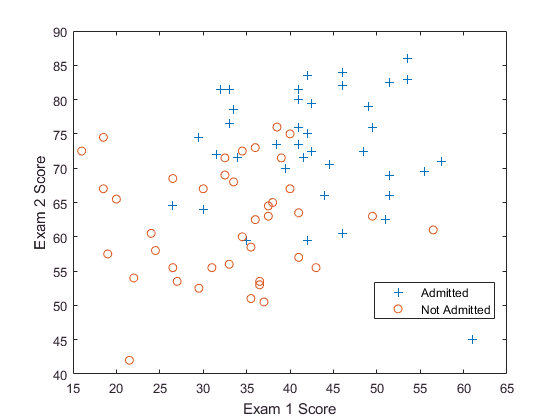

pos = find(y==1);
neg = find(y==0);

plot(x(pos,1),x(pos,2),'+'); hold on
plot(x(neg,1),x(neg,2),'o')
xlabel('Exam 1 Score'); ylabel('Exam 2 Score'); legend('Admitted','Not Admitted','location','best') 

tic;
obj = logical_object(x,y,10);
[final_theta,err] = newton_vectorized(obj);

Epoch  1: current theta values: 00, 00, 
 00. 
Epoch  2: current theta values: -9.08e+00, 8.32e-02, 
 8.80e-02. 
Epoch  3: current theta values: -1.39e+01, 1.25e-01, 
 1.35e-01. 
Epoch  4: current theta values: -1.60e+01, 1.45e-01, 
 1.56e-01. 
Epoch  5: current theta values: -1.64e+01, 1.48e-01, 
 1.59e-01. 
Epoch  6: current theta values: -1.64e+01, 1.48e-01, 
 1.59e-01. 
Epoch  7: current theta values: -1.64e+01, 1.48e-01, 
 1.59e-01. 
Epoch  8: current theta values: -1.64e+01, 1.48e-01, 
 1.59e-01. 
Epoch  9: current theta values: -1.64e+01, 1.48e-01, 
 1.59e-01. 
Epoch 10: current theta values: -1.64e+01, 1.48e-01, 
 1.59e-01. 


toc;

Elapsed time is 0.049806 seconds.


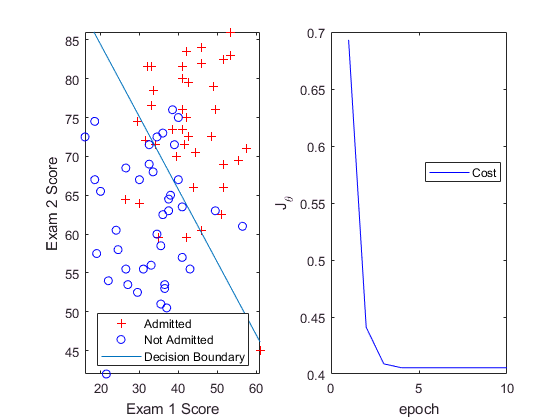

plot_graph(obj,final_theta,err);

## Probability that a student with a score of 20 on Exam 1 and a score of 80 on Exam 2 will not be admitted?

g = @(z) 1.0 /(1.0 + exp(-z));

prediction = 1 - g([1,20,80]*final_theta') %% 1 minus the answer for chance of NOT being admitted

prediction = 0.6680

## Implement non-vectorized version for 10 iterations

clear; clc

tic;
[final_lambda] = newton_nonVectorized(10)

final_lambda =    -0.0228    0.0103   -0.0026


toc;

Elapsed time is 0.035752 seconds.


## Implement non-vectorized version for 50,000 iterations

clear; clc

tic;
[final_lambda] = newton_nonVectorized(50000)

final_lambda =   -16.2499    0.1474    0.1576


toc;

Elapsed time is 16.354758 seconds.
